# Week 4: Data Analysis Applicaton on Dark Triad Personality Traits

## About the Dataset

The dark triad is a term in psychology used to refer to the traits of Machiavelianism, Narcissism,and Psychopathy. 

- Machiavelianism is charactarized by manipulation of others for one's own gain

- Narcissism means having a inflated sense of self esteem and self-gradiosity

- Psychopathy is similar to antisocial personality disorder, which is often described as lacking a concience, and also has the charactaristics of impulsivity and selfishness

People scoring high on these tests are more likely to do things that hurt society. 

## The Main Question

The goal of my work in this notebook is to validate the personality test. The question is: Do scores on each of the questions for sections of the dark triad correlate with each other? 

If the test is not a good measure of the traits, scoring highly on one question about Nacissism will not correlate with scoring highly on another question about Narcissism. This is the null hypothesis.

If the test is a good measure of traits, scoring highly on one question measuring Nacissism will correlate with scoring highly on another question about Narcissism. This is the alternative hypothesis. 

## Possible Secondary Questions

I would also want to see how much the dark triad personality traits correlate with each other. For example, if someone scores high in Psychopathy, are they also likely to score highly in Machiavelianism? And which traits correlate most highly with each other? Or are they independent?

There is also a datapoint for what country people came from, so it might be interesting to look at dark triad scores by country. The other extra piece of data is where they came from the test from (google search, main page of website), so I could do some analysis to see if there are any correlations bethween those factors. 

## Answering the Question

First do Pearson Correlation Coefficeint

Then try linear regression if time allows

data = readtable('data.csv');

size(data)

ans =        18192          29


average(data.M1)

ans = 4.1790

average(data.N1)

ans = 3.2695

average(data.P1)

ans = 3.0660

### Make data more useful

The questions for this dataset do not translate directly into scores for the traits in question. For exaple, the Narcissm section contains both statements such as: "I am an average person" and "Many group activities tend to be dull without me", which participants are asked to agree or disagree with. People who agree with the statment "Many group activities tend to be dull without me" would probably disagree with the statement "I am an average person", and vice versa. Agreeing with one statment would indicate high narcissism while agreeing with another would indicate low narcissism. I had to figure out a way to take this fact into account in order to do a good analysis of the data.

I looked up the name of the poster where this research was presented, and found a document that contained the methods that the researchers used to analysze the data. They simply reversed the scores on some of the questions, which were marked with "R." [http://www.midss.org/sites/default/files/d3.pdf](http://www.midss.org/sites/default/files/d3.pdf)

I decided to copy their method. 

The data was collected on a 5 point scale where 

1: Strongly Disagree

2: Disagree

3: Neither Agree nor Disagree

4: Agree

5: Strongly Agree

They did not state this, but there are some zeroes in the data. I assumed that these zeroes were outliers and removed them. 

% select only numeric data from table
n = vartype('numeric');
d = data(:, n);

% turn numeric data into array
da = table2array(d);
clear d

% select only data from questions
da = da(:, 1:27);
size(da)

ans =        18192          27



% remove all entries with zeros
i = find(da == 0);
% 748 is a reasonable number to remove
size(i)

ans =    748     1


for i = 1:size(i)
   da(i, :) = [];
end
size(da)

ans =        17444          27


% reverse value of questions for certain columns 
% (=columns N2, N6, N8, P2, P7)
% in array: 11, 15, 17, 20, 25
da(1:10, 11)

ans =      5
     1
     5
     1
     1
     2
     2
     4
     2
     4


reverse = [11, 15, 17, 20, 25];
for i = 1:size(reverse)
    da(:, i) = (da(:, i) *-1) + 5;
end
da(1:10, 11)

ans =      5
     1
     5
     1
     1
     2
     2
     4
     2
     4


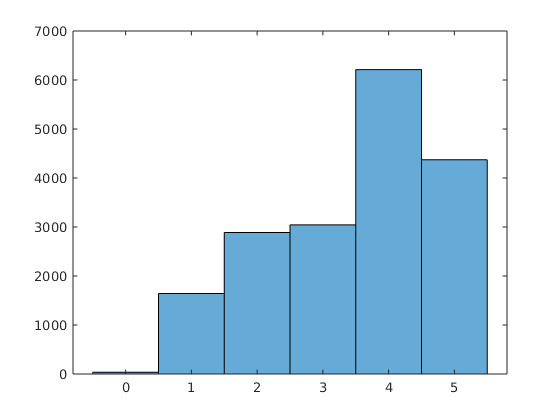

histogram(data.M2)

### Pearson Correlation Coefficeint

% tests if data is normally distributed (1 is yes)
h = lillietest(data.M1)

h = 1

R = corrcoef(((data.M1+data.M2)/2), ((data.M3+data.M4)/2))

R =     1.0000    0.5150
    0.5150    1.0000


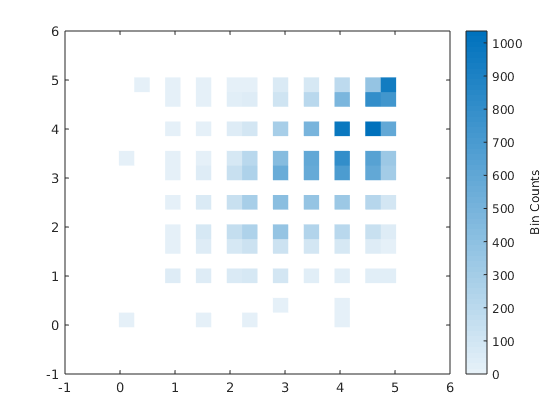

binscatter(((data.M1+data.M2)/2), ((data.M3+data.M4)/2))

[https://explorable.com/internal-consistency-reliability](https://explorable.com/internal-consistency-reliability)

#### Compare a lot of things

This block of code runs a for loop for 

i = 1;
avgc = 0;
for i = 1:7
    c = corrcoef(da(:, i), da(:, i+2));
    c(2)
    avgc = avgc + c(2)/27;
end

ans = -0.2984

ans = 0.3144

ans = 0.4945

ans = 0.3217

ans = 0.4066

ans = 0.4595

ans = 0.3656


for i = 9:16
    c = corrcoef(da(:, i), da(:, i+2));
    c(2)
    avgc = avgc + c(2)/27;
end

ans = -0.1096

ans = 0.4073

ans = -0.2592

ans = 0.3612

ans = -0.2666

ans = 0.3382

ans = 0.3328

ans = 0.3096


for i = 18:25
    c = corrcoef(da(:, i), da(:, i+2));
    c(2)
    avgc = avgc + c(2)/27;
end

ans = -0.1827

ans = 0.4261

ans = -0.3115

ans = 0.3601

ans = 0.3303

ans = -0.1396

ans = 0.2798

ans = -0.1460

avgc

avgc = 0.1405

### K-Means Clustering 

I did not really get this to work with the data

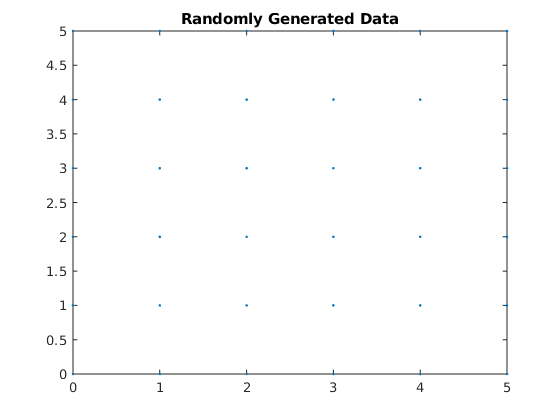

rng default; % For reproducibility
M = da(:, 1:9);
M = M(:);
N = da(:, 10:18);
N = N(:);
P = da(:, 19:27);
P = P(:);

% trying to see if M and N scores cluster differently
X = [M, N];

figure;
plot(X(:,1),X(:,2),'.');
title 'Randomly Generated Data';

opts = statset('Display','final');
[idx,C] = kmeans(X,2,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 1 iterations, total sum of distances = 273257.
Replicate 2, 1 iterations, total sum of distances = 266301.
Replicate 3, 2 iterations, total sum of distances = 270315.
Replicate 4, 1 iterations, total sum of distances = 266301.
Replicate 5, 1 iterations, total sum of distances = 310257.
Best total sum of distances = 266301


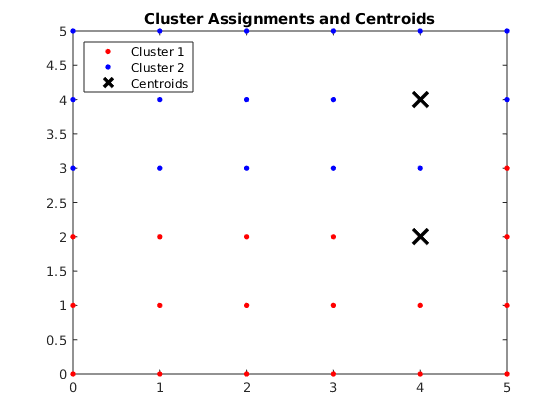


figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off;

% hmm, not sure how to interpret this